# Thuật toán

[Menu menu chính](matlab:open('MainMenu.mlx'))

Tên chính thức cho một quy trình được xác định rõ ràng có thể được theo sau bởi một máy tính là một thuật toán. Bạn đã biết một số thuật toán từ toán học và bạn có thể đã gặp chúng ở nơi khác trong cuộc sống của bạn cũng như các quy trình như tìm kiếm một từ trong từ điển giấy hoặc sắp xếp một bàn tay của thẻ theo thứ tự tiêu chuẩn. Bạn có thể ít quen thuộc với việc thể hiện các thuật toán rõ ràng và chính xác.

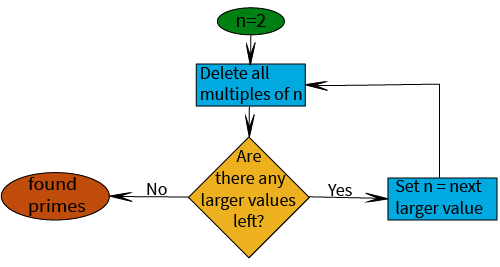

## Communicating Algorithms

Có nhiều cách để diễn đạt một thuật toán, nhưng phổ biến nhất là viết ra quy trình trong các câu tiêu chuẩn hoặc trong giả giả. Mã giả là một thuật ngữ có nghĩa là một bộ sưu tập nhỏ các từ và ký hiệu chính thức có thể được kết hợp với định dạng và một lượng nhỏ văn bản để mô tả một thuật toán có thể được thực hiện trong bất kỳ ngôn ngữ lập trình nào bởi một lập trình viên quen thuộc với ngôn ngữ.

### Các tính năng chung của mã giả

- Một biểu tượng biểu thị rằng phần còn lại của dòng là một nhận xét. Đến từ môi trường MATLAB, tập lệnh này sẽ sử dụng`Phần trăm`như nhân vật bình luận.

- `Một`$\ Leftarrow$`b`có nghĩa là "A được gán giá trị của B"

- Các biểu tượng toán học tiêu chuẩn như +, *, <cũng như các ký hiệu toán học từ toán học riêng biệt như \ ("Set Difference"), ~ ("logic không"), & ("logic và") và == ("bằng logic").

- Nhận dạng trình tự`Điểm bắt đầu đến điểm cuối`means the set of value

`{StartPoint, startPoint + 1, startPoint + 2, ..., điểm cuối - 2, điểm cuối -1, điểm cuối`

Similarly, if the step size between values isn't 1, that can be indicated by

`StartPoint by StepSize to EndPoint` 

to mean the list of values

`{StartPoint, StartPoint + StepSize, StartPoint + 2*StepSize, ... , StartPoint+m*StepSize}` 

Ở đâu (`EndPoint-StartPoint)/(m+1) < StepSize, but (EndPointSstartPoint)/m`$\ geq$S`tepSize.`

5. Logic kiểm soát tiêu chuẩn:`while, for, if/else.`

### Ví dụ: Thể hiện trò chơi Chaos Square Square đơn giản như một thuật toán

`Điểm khởi đầu`$\ Leftarrow$`random point`

`Numpts`$\ Leftarrow$`số lần lặp`

`for k = 1 to NumPts`

`NewCorner`$\ Leftarrow$`randomly selected corner coordinates`

`NextPoint`$\ Leftarrow$`Khởi động + (Newcorner-startingPoint)/2`

`Đồ thị NextPoint`

`Điểm khởi đầu`$\ Leftarrow$N`extpoint`

## Mã hóa một bài toán đơn giản

Tất cả các số nguyên tố nhỏ hơn hoặc bằng 100 là gì? Đây là một vấn đề thẳng về mặt tính toán với một số giải pháp thuật toán phổ biến. Một số nguyên dương$N$là nguyên tố nếu các yếu tố duy nhất của nó là$1$Và$N$

**Thuật toán 1:**Lặp đi lặp lại danh sách tất cả các số nguyên tố nhỏ hơn hoặc bằng$N$lên đến`Giá trị tối đa`

    `% Nhận ra rằng 2 là số nguyên tố nhỏ nhất.`

    `% Khi n = 2, số nguyên tố duy nhất ít hơn hoặc bằng n là`$2$

`Primelist`$\ Leftarrow$`2`

`cho n trong 3 đến tối đa`

`cho p trong nguyên thủy`

`Nếu n`[`Mod`](https://www.mathworks.com/help/matlab/ref/mod.html)`P == 0`

`n là tổng hợp và có thể bị bỏ qua`

`nếu không có số nguyên tố trong nguyên thủy là yếu tố của n`

`nối n vào primelist`

Primelist = 2;
cho n = 3: 100
    Notprimeflag = 0;
    cho p = primelist
        Nếu mod (n, p) == 0
            Notprimeflag = 1;
        otherif p == primelist (end) && notprimeflag == 0
            Primelist = [Primelist N];
        kết thúc
    kết thúc
kết thúc
Primelist

**Thuật toán 2:**Giả sử tất cả các số có thể lên đến`Giá trị tối đa`, sau đó lặp đi lặp lại bội số của các giá trị nhỏ hơn.

`Primelist`$\ Leftarrow$`2 đến tối đa`

`P`$\ Leftarrow$`2`

`chỉ mục`$\ Leftarrow$`1`

`Trong khi p <sqrt (tối đavalue)`

`Primelist`$\ Leftarrow$`Primelist \ (2*p bởi P đến MaximumValue)`

`chỉ mục`$\ Leftarrow$`Chỉ mục + 1`

`P`$\ Leftarrow$`Primelist (Index)`

**Bài tập 1**

a) Thực hiện thuật toán 2.

b) Time how long Algorithm 1 and Algorithm 2 take to determine all the primes up to 100. Which implementation is more efficient? Tại sao?

c) Thời gian thuật toán 1 và thuật toán 2 mất bao lâu để xác định tất cả các số nguyên tố lên tới 10.000. Việc thực hiện nào hiệu quả hơn? Tại sao?

  **Pro-tip**. Hãy nhớ rằng bạn có thể sử dụng tài liệu để tìm kiếm các chức năng, đối số tùy chọn và cú pháp. Hãy thử một vài tùy chọn ở đây như tìm kiếm web chung:

Hoặc tìm kiếm tài liệu địa phương cụ thể như:

Thách thức là nếu bạn không nhớ thuật ngữ tiêu chuẩn, trong trường hợp tìm kiếm có thể khó xử hoặc không thể cho đến khi bạn có thể xác định những gì người khác gọi bất cứ điều gì bạn đang tìm kiếm.

% Mã giải pháp của bạn cho bài tập 1 tại đây

Primelist

### Kiểm tra và bằng chứng về tính chính xác

Mặc dù bài kiểm tra không thể tránh khỏi về tính chính xác cho mã là liệu nó có biên dịch và chạy hay không, nhưng điều quan trọng là phải đảm bảo rằng nó thực hiện chính xác thuật toán và thuật toán giải quyết vấn đề mà nó dự định giải quyết. Trong thực tế, có một lỗi trong thuật toán 1 hoặc thuật toán 2.

**Bài tập 2**

Sử dụng cả thuật toán 1 và thuật toán 2 để tính toán số nguyên tố nhỏ hơn hoặc bằng 25. Bạn có nhận được kết quả tương tự không? Nếu không, sự khác biệt là gì và tại sao? Làm thế nào để bạn sửa chữa thuật toán thích hợp? Điều đó làm gì với mã của bạn?

#### Kiểm tra đơn vị

Bằng cách chia mã của bạn thành các thành phần đơn giản, nơi bạn có thể kiểm tra xem đầu vào và đầu ra có phù hợp với những gì bạn mong đợi, bạn có thể chính thức kiểm tra hoặc không chính thức mã của bạn có hoạt động chính xác không. Điều này cũng có thể giúp cô lập nguyên nhân của một lỗi mà bạn biết nhưng chưa xác định được bản sửa lỗi. Nếu chúng ta xem xét việc thực hiện thuật toán 1, thì các đơn vị nhỏ nhất sẽ là các dòng riêng lẻ như

hoặc

Và chạy thử nghiệm đơn vị có thể chỉ cần chạy mã với dòng đó không bị áp dụng hoặc nếu bạn không có toàn bộ chương trình được xây dựng nhưng bạn có thể chạy thử nghiệm đơn vị bằng cách xác định các giá trị sẽ đến và chạy thử nghiệm đơn vị để xem những gì phát ra.

% Đặt giá trị để kiểm tra
Primelist = [2 3 5 7];
n = 11;

% Kết quả dự kiến?
PrimelisTexpected = [2 3 5 7 11]

% Chạy kiểm tra
Primelist = [Primelist N]

Đối với các chương trình hoặc đầu ra lớn hơn, bạn có thể không muốn kiểm tra bằng tay. Nói chung, các ngôn ngữ lập trình cấp cao có các chức năng tích hợp để giúp kiểm tra như khả năng ném một ngoại lệ bằng cách phản hồi các loại lỗi cụ thể với thông báo tiêu chuẩn hoặc bằng cách ghi lại các giả định trong mã của bạn với các xác nhận.

Assert (isequal (primelist, primelisTexpected))

  **Thử**. Sửa đổi mã trên để`Primelist`không phù hợp`nguyên thủy`và chạy lại mã. Điều gì xảy ra bây giờ?

Trong trường hợp của một nhánh hoặc một vòng lặp, bạn muốn kiểm tra rằng logic tuân theo đường dẫn bạn đã lên kế hoạch bằng cách thiết lập các giá trị đầu vào dẫn đến mỗi đường dẫn thông qua mã.

#### Trường hợp cạnh

Một lớp phổ biến của các lỗi lập trình là những lỗi phát sinh dọc theo ranh giới. Bạn đã kiểm tra những gì xảy ra ở các giá trị rất lớn hoặc rất nhỏ? Còn 0, đó là ranh giới giữa các số dương và số âm? Có bất bình đẳng nào không? Họ có nên nghiêm khắc hay không?

### **Ứng dụng: Caesar Mật mã**

`Pleasecodethis (InputString, Inshift)`là một hàm có một chuỗi và một sự thay đổi và thực hiện mật mã Caesar, giúp chuyển từng chữ cái của bảng chữ cái về phía trước (hoặc lùi) bằng cách`Chịu đựng`địa điểm.

chức năng vượt xa = pleasecodethis (InputString, Inshift)
% Chuyển đổi đầu vào thành ASCII
NumString = int8 (char (inputString));
Phía ngoài = số lượng;
Bdryvals = int8 ('azaz');
% Kiểm tra xem ký tự đầu vào là một chữ cái chưa và nếu vậy, hãy mã hóa nó
% thích hợp
cho k = 1: chiều dài (số)
    if (numString (k)> = bdryvals (1) && numString (k) <= bdryvals (2)) |
        Phía ngoài (k) = numString (k)+inshift;
    kết thúc
kết thúc
% Chuyển đổi ASCII trở lại một chuỗi
Phía ngoài = ConvertCharToStrings (char (vượt trội));
kết thúc

Trong lịch sử, điều này thường được thực hiện với các đĩa lồng nhau. Trong mô hình bên dưới, vòng ngoài được cố định và vòng bên trong có thể quay.

  **Thử**. Chạy mã bên dưới với các đối số khác nhau bằng cách thay đổi giá trị của thanh trượt.

thay đổi = 20;
Caesarciphertool (Shift)

Pleasecodethis ("Ngày xửa ngày xưa ...", Shift)

**Bài tập 3**

Chức năng`Pleasecodethis`Chỉ hoạt động trong một số trường hợp. Đối với những giá trị nào nó thất bại và tại sao? Giải thích cách bạn sẽ sửa nó.

## **Ứng dụng: Mật mã trực quan**

Xem xét các ví dụ sau đây hình ảnh đen trắng được lưu trữ trong`M1`Và`M2`Bằng cách chạy khối mã bên dưới. Bạn có thấy bất kỳ mẫu nào không?

Tải ("EncryptedImage.mat")
imshow (M1)
imshow (M2)

Bây giờ hãy xem xét hình ảnh sau được tạo bằng cách trừ hai ma trận và lấy giá trị tuyệt đối. Bạn có thấy bất kỳ mẫu nào không?

imshow (abs (m1-m2))

  **Thử**

- Điều gì xảy ra nếu bạn sử dụng`imshow`Trên ma trận`M1-M2`mà không có giá trị tuyệt đối?

- Điều gì xảy ra nếu bạn sử dụng`imshow`Trên ma trận`M1+M2`? Điều này có thay đổi với một giá trị tuyệt đối không?

 **Phản ánh**

- Tại sao bạn nghĩ điều này xảy ra?

- Sự khác biệt giữa thêm và trừ đi là gì?

**Bài tập 4**

Thực hiện một thuật toán mật mã hình ảnh đơn giản để biến hình ảnh màu đen và trắng thành hai hình ảnh xuất hiện hỗn loạn trên thực tế các tác phẩm cân bằng cẩn thận với số lượng pixel trắng và pixel màu trắng bằng nhau. Tóm lại, thay thế từng pixel trắng bằng bốn pixel mới trong mỗi cặp hình ảnh được chuyển đổi bằng mật mã:

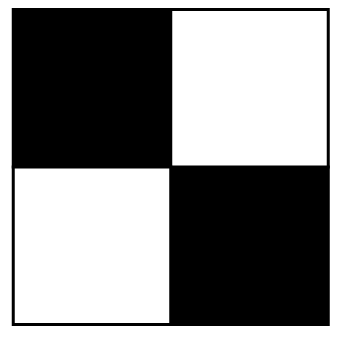Vàhoặc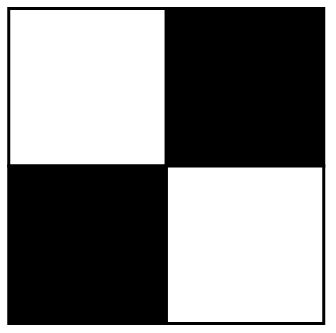VàThì

và thay thế từng pixel màu đen trong hình ảnh gốc tương tự

VàhoặcVà

Khi được kết hợp lại, chỉ theo dõi các pixel màu đen, lưu ý rằng các vùng trắng hiện chính xác là 50% pixel trắng và 50% pixel đen trong các kết hợp ngẫu nhiên sẽ xuất hiện ở mắt dưới dạng màu xám ở quy mô đủ. Các vùng màu đen được bảo tồn. Điều này cũng làm cho nó có thể định dạng lại và tái tạo trở lại hình ảnh gốc với độ trung thực hoàn toàn nếu muốn.

**Thuật toán mật mã hình ảnh đơn giản**

`Bắt đầu`$\ Leftarrow$`Ma trận của 1 và 0`

`SX`$\ Leftarrow$`Số lượng hàng trong khởi đầu`

`Sy`$\ Leftarrow$`Số lượng cột bắt đầu`

`Khởi tạo hai ma trận, IM1 và IM2 có kích thước 2*sx bằng 2*sy`

`cho j = 1 đến sx`

`cho k = 1 đến sy`

`Flip = lựa chọn ngẫu nhiên là 0 hoặc 1`

`Nếu bắt đầu (j, k) == 1`

`Nếu Flip == 0`

`IM1 (2*J-1: 2*J, 2*K-1: 2*K)`$\ Leftarrow$`[1 0; 0 1]`

`IM2 (2*J-1: 2*J, 2*K-1: 2*K)`$\ Leftarrow$`[0 1; 1 0]`

                        `khác`

                        `IM2 (2*J-1: 2*J, 2*K-1: 2*K)`$\ Leftarrow$`[1 0; 0 1]`

`IM1 (2*J-1: 2*J, 2*K-1: 2*K)`$\ Leftarrow$`[0 1; 1 0]`

`khác`

`Nếu Flip == 0`

`IM1 (2*J-1: 2*J, 2*K-1: 2*K)`$\ Leftarrow$`[1 0; 0 1]`

`IM2 (2*J-1: 2*J, 2*K-1: 2*K)`$\ Leftarrow$`[1 0; 0 1]`

                        `khác`

                        `IM2 (2*J-1: 2*J, 2*K-1: 2*K)`$\ Leftarrow$`[0 1; 1 0]`

`IM1 (2*J-1: 2*J, 2*K-1: 2*K)`$\ Leftarrow$`[0 1; 1 0]`                      

Thực hiện thuật toán này. Kiểm tra kết quả của bạn trên các hình ảnh sau đây bạn đã chơi với:

% Xóa không gian làm việc của tất cả các biến hiện tại
ClearVars ()
% Tải hình ảnh mẫu
Tải ("bw_images.mat")
% In danh sách các hình ảnh hiện đang ở trong không gian làm việc
ai

% Chọn một hình ảnh và gọi nó là IM0

% Mã giải pháp để tập 4 ở đây để biến IM0 thành hai hình ảnh IM1 và
% IM2 sử dụng thuật toán mật mã trực quan được đưa ra

% Unmment Dòng bên dưới để hiển thị kết quả của bạn
% Montage ({IM0, ABS (IM1-IM2), IM1, IM2}))

 **Phản ánh**

- Có phải mật mã trực quan chỉ áp dụng cho hình ảnh đen trắng?

- Bạn có thể phác thảo một thuật toán sẽ mã hóa một hình ảnh bằng màu không?

- Nếu bạn có nhiều phạm vi để làm việc với (thang độ xám hoặc màu), bạn có thể phác thảo một thuật toán sẽ mã hóa một hình ảnh bên trong một hình ảnh thay vì yêu cầu một cặp?

- Có cách sử dụng gì cho mật mã trực quan?

[Menu menu chính](matlab:open('MainMenu.mlx'))

## Chức năng trợ giúp

#### Pleasecodethis (InputString, Inshift)

#### Mã tạo hình ảnh

Hàm Caesarciphertool (Shift)
thử
    % Kiểm tra xem ca làm việc là một số nguyên
    khẳng định (vòng (shift) == shift);
    khẳng định (regexp (chuỗi (shift), "[0-9].*"));

    nhân vật
    % Vẽ và che bóng các vòng tròn có liên quan
    ThemeObj = Theme ();
    Nếu ThemeObj.BasecolorStyle == "Ánh sáng"
        Basecolor = [1 1 1];
    otherif ThemeObj.basecolorstyle == "Dark"
        Basecolor = [0 0 0];
    khác
        Basecolor = "Không";
    kết thúc
    Hình chữ nhật ("vị trí", [ -1 -1 2 2], "độ cong", [1 1], "facecolor", Basecolor)
    Hình chữ nhật ("vị trí", [ -. 75 -.75 1.5 1.5], "độ cong", [1 1], "facecolor", [. 9 .9 .9])
    Hình chữ nhật ("vị trí", [ -. 5 -.5 1 1], "độ cong", [1 1], "facecolor", basecolor)
    % Thiết lập kích thước bước góc cần thiết để hiển thị bảng chữ cái
    Dtheta = 360/26;
    % Tắt trục x và y và làm cho vòng tròn
    trục vuông
    giữ lấy
    Bảng chữ cái = 'abcdefghijklmnopqrstuvwxyz';
    cho k = 1:26
        % Sử dụng một phông chữ có chiều rộng cố định để mỗi chữ cái được tập trung trong phần của nó
        Văn bản (0,9*sind ((K-1)*dtheta), 0,9*cosd ((K-1)*dtheta), bảng chữ cái (k), ...
            "Xoay", (1-K)*dtheta, "fontname", "FixedWidth", "font weight", "in đậm");
        Văn bản (0,6*sind ((k-shift-1)*dtheta), 0,6*cosd ((k-shift-1)*dtheta), bảng chữ cái (k), ...
            "Xoay", (1-K+Shift)*Dtheta, "FontName", "FixedWidth", "Font weight", "in đậm", ...
            "Màu", [0 0 0]);
        % Cốt truyện chia các dòng; Chuyển sang 3/5*Dtheta để tính toán chiều rộng của các chữ cái
        Lô đất ([-Sind ((K-3/5)*Dtheta) -0.5*Sind ((K-3/5)*Dtheta)], ...
            [COSD ((K-3/5)*Dtheta) 0,5*COSD ((K-3/5)*Dtheta)], ...
            Series Index = 1)
    kết thúc
    Giữ lấy
bắt tôi
    % Nếu xác nhận không thành công, hãy hiển thị cảnh báo và không cố gắng chạy
    % phần còn lại của mã
    phân tán (tôi.Message)
    CẢNH BÁO ("Việc dịch chuyển theo giá trị không số nguyên có thể không tạo ra mã có thể sử dụng được.")
kết thúc
kết thúc